Les forces musculaires f0 ont été mutipliés par 10, On affiche les muscles pour lesquels ont a des activations supérieur à 0.1.

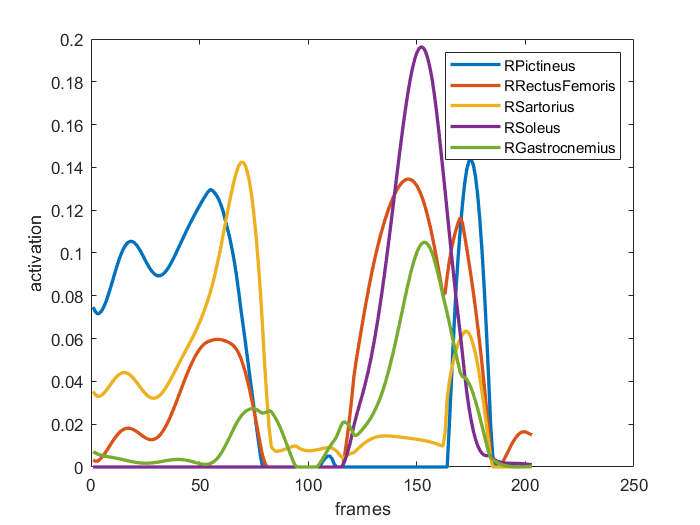

load('C:\Users\ppuchaud\Documents\MATLAB\CusToM\Debug_saturation\ChgtDirection04\MuscleForcesComputationResults.mat')
load('BiomechanicalModel.mat')
a=MuscleForcesComputationResults.MuscleActivations;
plot(a(logical(sum(a>=0.1,2)),:)','LineWidth',2)
legend({BiomechanicalModel.Muscles(logical(sum(a>=0.1,2))).name})
xlabel('frames')
ylabel('activation')

To do : check bras de levier

Check EMG signals

addpath(genpath('C:\Users\ppuchaud\Documents\MATLAB\MOtoNMS'))

h=btkReadAcquisition('ChgtDirection04.c3d')

h = 3.4400e-315

[hh,Anainfo]=btkGetAnalogs(h)

hh = struct with fields:
               Force_Fx1: [1015×1 double]
               Force_Fy1: [1015×1 double]
               Force_Fz1: [1015×1 double]
              Moment_Mx1: [1015×1 double]
              Moment_My1: [1015×1 double]
              Moment_Mz1: [1015×1 double]
               Force_Fx2: [1015×1 double]
               Force_Fy2: [1015×1 double]
               Force_Fz2: [1015×1 double]
              Moment_Mx2: [1015×1 double]
              Moment_My2: [1015×1 double]
              Moment_Mz2: [1015×1 double]
               Force_Fx3: [1015×1 double]
               Force_Fy3: [1015×1 double]
               Force_Fz3: [1015×1 double]
              Moment_Mx3: [1015×1 double]
              Moment_My3: [1015×1 double]
              Moment_Mz3: [1015×1 double]
    Electric_Potential_1: [1015×1 double]
        Voltage_GM_Droit: [1015×1 double]
        Voltage_BF_Droit: [1015×1 double]
        Voltage_RF_Droit: [1015×1 double]
        Voltage_VL_Droit: [1015×1 double]
        V

Anainfo = struct with fields:
          label: [1×1 struct]
    description: [1×1 struct]
           gain: [1×1 struct]
         offset: [1×1 struct]
          scale: [1×1 struct]
      frequency: 1000
          units: [1×1 struct]


names=fieldnames(Anainfo.label);
Ind = cellfun(@(X)contains(X,'Voltage'),names);
f=names(Ind)

f = 16×1 cell array
    {'Voltage_GM_Droit'   }
    {'Voltage_BF_Droit'   }
    {'Voltage_RF_Droit'   }
    {'Voltage_VL_Droit'   }
    {'Voltage_TA_Droit'   }
    {'Voltage_PL_Droit'   }
    {'Voltage_Sol_Droit'  }
    {'Voltage_GasL_Droit' }
    {'Voltage_GM_Gauche'  }
    {'Voltage_BF_Gauche'  }
    {'Voltage_RF_Gauche'  }
    {'Voltage_VL_Gauche'  }
    {'Voltage_TA_Gauche'  }
    {'Voltage_PL_Gauche'  }
    {'Voltage_Sol_Gauche' }
    {'Voltage_GasL_Gauche'}


for ii=1:length(f)
    labels{ii}=Anainfo.label.(f{ii});
end

parameters.EMGsSelected.OutputLabels=labels;
parameters.EMGsSelected.C3DLabels=labels;
parameters.EMGOffset = 0;
parameters.MaxEmgTrialsList={'ChgtDirection04'};
parameters.OutputFileFormats.EMG='.mot';
parameters.trialsList={'ChgtDirection04'}

parameters = struct with fields:
         EMGsSelected: [1×1 struct]
            EMGOffset: 0
     MaxEmgTrialsList: {'ChgtDirection04'}
    OutputFileFormats: [1×1 struct]
           trialsList: {'ChgtDirection04'}



foldersPath.elaboration ='C:\Users\ppuchaud\Documents\MATLAB\CusToM\Debug_saturation\elaboration\';
foldersPath.sessionData ='C:\Users\ppuchaud\Documents\MATLAB\CusToM\Debug_saturation\sessionData\';
trialsList=parameters.trialsList;
foldersPath.trialOutput= mkOutputDir(foldersPath.elaboration,trialsList)

foldersPath = struct with fields:
    elaboration: 'C:\Users\ppuchaud\Documents\MATLAB\CusToM\Debug_saturation\elaboration\'
    sessionData: 'C:\Users\ppuchaud\Documents\MATLAB\CusToM\Debug_saturation\sessionData\'
    trialOutput: {'C:\Users\ppuchaud\Documents\MATLAB\CusToM\Debug_saturation\elaboration\\ChgtDirection04\'}



AnalogFrameRate=Anainfo.frequency

AnalogFrameRate = 1000


[~,info]=btkGetMarkers(h)

info = struct with fields:
    frequency: 200
        units: [1×1 struct]



AnalysisWindow{1}.LabeledDataOffset= btkGetFirstFrame(h)-1;
AnalysisWindow{1}.startFrame=1;
AnalysisWindow{1}.endFrame=btkGetLastFrame(h)-btkGetFirstFrame(h);
AnalysisWindow{1}.rate=info.frequency

AnalysisWindow = 1×1 cell array
    {1×1 struct}



EMGOFileFormat='.mat'

EMGOFileFormat = '.mat'


%AnalysisWindow{1}.LabeledDataOffset=   AnalysisWindow{1}.startFrame-1
EMG_traitement();

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
             EMG PROCESSING                    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Max values for selected emg signals have been computed
Printed maxemg.txt


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Printed emg.mot


Plotted EMGs
